load('pilot_master_long.mat')

master = sortrows(master,"Pair","ascend");

%% ALL SUBJECTS %%%
% clearvars -except subtable
% master = sortrows(subtable,"Pair","ascend");

cuehl = master.highcue_indx;
cuemean = master.cue_observed_mean;
pair = master.Pair;
rating = master.img_rate;
stimmean = master.Valence_mean;

wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table_all = master(wh_high, :);
lo_table_all = master(wh_low, :);

numArrays = 4;
groups = cell(numArrays,1);
for n = 1:numArrays
    hi_table = hi_table_all(hi_table_all.group == n, :);
    lo_table = lo_table_all(lo_table_all.group == n, :);

pair_table = table;
pair_table.pair_number = hi_table.Pair;
pair_table.hi_cue = hi_table.img_rate;
pair_table.lo_cue = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_cue - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_cue - pair_table.rating_mean;
d = pair_table.rating_diff;

% Two-tailed
% [hyp, pval, ci, stat] = ttest(pair_table.hi_cue, pair_table.lo_cue, 'Tail', 'right', 'Alpha', 0.999);
[hyp, pval, ci, stat] = ttest2(pair_table.hi_cue, pair_table.lo_cue, ...
'Tail', 'right', 'Alpha', 0.999, 'Vartype', 'unequal'); % Assumes unequal variance
% 

fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));
groups{n}.hyp = hyp;
groups{n}.pval = pval;
groups{n}.ci = ci;
groups{n}.stat = stat;
groups{n}.pair_table = pair_table;
groups{n}.d = d;
groups{n}.SE = ste(d);
groups{n}.mean = mean(pair_table.rating_diff);
end

High vs. low cue effect: M = 4.55, SE = 0.56, t(2046) = 3.36, p = 0.000390
High vs. low cue effect: M = 4.26, SE = 0.54, t(1917) = 2.99, p = 0.001404
High vs. low cue effect: M = 3.72, SE = 0.58, t(1982) = 2.66, p = 0.003989
High vs. low cue effect: M = 4.21, SE = 0.60, t(1915) = 3.18, p = 0.000758


nu = stat.df;
k = linspace(-15,15,300);
tdistpdf = tpdf(k,nu);
tval = stat.tstat

tval = 3.1763

tvalpdf = tpdf(tval,nu);
tcrit = tinv(0.999,nu)

tcrit = 3.0945

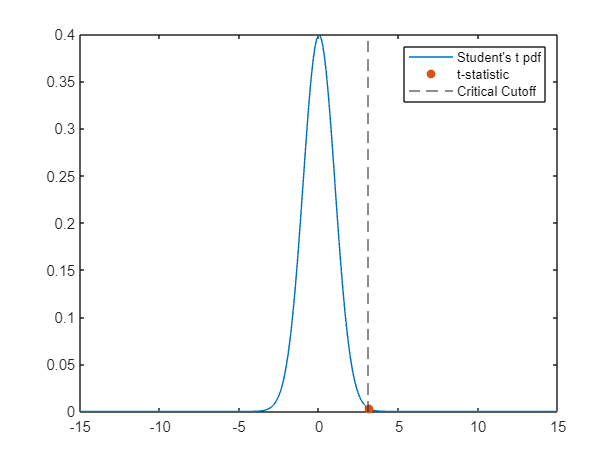

plot(k,tdistpdf)
hold on
scatter(tval,tvalpdf,"filled")
xline(tcrit,"--")
legend(["Student's t pdf","t-statistic", ...
    "Critical Cutoff"])
hold off;

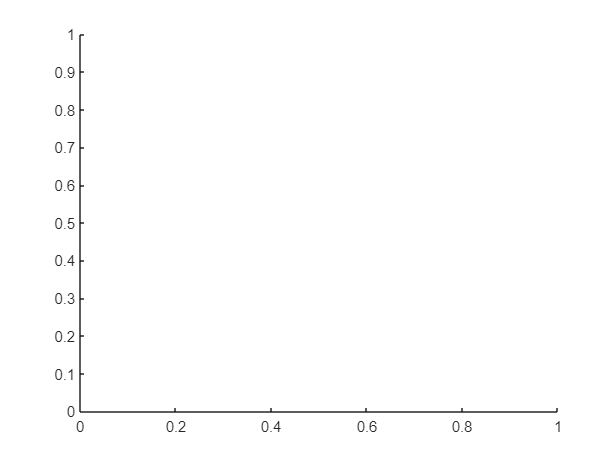



%%
figure; hold on;

for i = 1:4
    y(i) = groups{i}.mean;
    SEs(i) = groups{i}.SE;
    errlow(i) = groups{i}.mean - groups{i}.SE;
    errhigh(i) = groups{i}.mean + groups{i}.SE;
end
b = bar([1 2 3 4], y );

Error using bar
The length of X must match either the number of rows or the number of columns of Y.

b.FaceColor = 'flat';
b.CData(1, :) = [1 .95 0];
b.CData(3, :) = [1 .95 0];

b.CData(2, :) = [0 .9 .2];
b.CData(4, :) = [0 .9 .2];
er = errorbar(1:4,y,SEs);

er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
er.LineWidth = 2;

set(gca, 'FontSize', 32)
scn_export_papersetup(400);
ylabel('Percent Increase', 'FontWeight', 'bold');
xlabel('Group Number', 'FontWeight', 'bold');
title('Cue Effect Evident in All Pilot Groups')
set(gca, 'XTick', 1:4, 'XTickLabel', ['1a'; '1b'; '2a'; '2b']);
drawnow()
hold off;

hicue_val = (master.img_rate(master.highcue_indx == 1));
locue_val = (master.img_rate(master.highcue_indx == -1));

highmean = mean(hicue_val);
lowmean = mean(locue_val);
[h,p,ci,stats] = ttest(hicue_val, locue_val)

h = 1

p = 9.7374e-48

ci =     3.6268
    4.7421


stats = struct with fields:
    tstat: 14.7124
       df: 3935
       sd: 17.8436


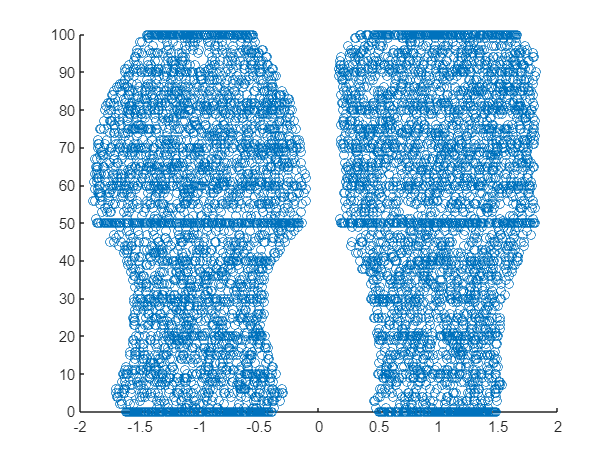


figure; hold on; 
swarmchart(master.highcue_indx, master.img_rate)

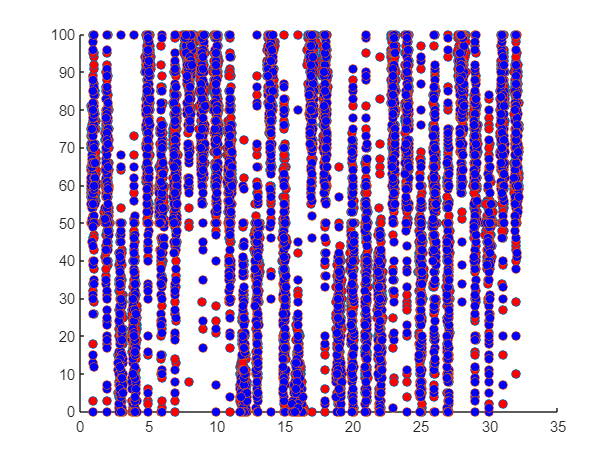


figure; hold on; 
swarmchart(master.Pair(master.highcue_indx == 1), master.img_rate(master.highcue_indx == 1), 'o', 'MarkerFaceColor', 'r')
swarmchart(master.Pair(master.highcue_indx == -1), master.img_rate(master.highcue_indx == -1), 'o', 'MarkerFaceColor', 'b')


hold off;